# Proyecto Métodos Numéricos

clear
clc



## Desarrollo teórico

syms Theta_1(t) Theta_2(t) Theta_3(t) R_1(t) t
syms r_1 r_1y r_2 r_3
syms theta_1 theta_2 theta_3 
syms V_r omega_1 omega_2 omega_3 
syms a_r alpha_1 alpha_2 alpha_3

Vr_2=0.075

Vr_2 = 0.0750

Vr_3=0.17

Vr_3 = 0.1700

Vr_1y=0.045

Vr_1y = 0.0450


Fc=sin(Theta_1)*R_1-r_1y;
fc=subs(Fc,[Theta_1, R_1],[theta_1, r_1]);

Fx=-R_1*cos(Theta_1)+r_2*cos(Theta_2)+r_3*cos(Theta_3);
Fx=simplify(Fx,'Steps',5);
fx=formula(subs(Fx,[Theta_1, Theta_2, Theta_3, R_1],[theta_1, theta_2, theta_3, r_1]));

Fy=R_1*sin(Theta_1)-r_2*sin(Theta_2)-r_3*sin(Theta_3);
Fy=simplify(Fy,'Steps',5);
fy=formula(subs(Fy,[Theta_1, Theta_2, Theta_3, R_1],[theta_1, theta_2, theta_3, r_1]));

DFcDt=diff(Fc);
DFxDt=diff(Fx);
DFyDt=diff(Fy);
F1=formula(subs(DFxDt,[diff(R_1),diff(Theta_1),diff(Theta_2),diff(Theta_3),Theta_1,Theta_2,Theta_3,R_1],[V_r,omega_1,omega_2,omega_3,theta_1,theta_2,theta_3,r_1]));
F2=formula(subs(DFyDt,[diff(R_1),diff(Theta_1),diff(Theta_2),diff(Theta_3),Theta_1,Theta_2,Theta_3,R_1],[V_r,omega_1,omega_2,omega_3,theta_1,theta_2,theta_3,r_1]));
F3=formula(subs(DFcDt,[diff(R_1),diff(Theta_1),diff(Theta_2),diff(Theta_3),Theta_1,Theta_2,Theta_3,R_1],[V_r,omega_1,omega_2,omega_3,theta_1,theta_2,theta_3,r_1]));

D2FcDt2=diff(DFcDt);
D2FxDt2=diff(DFxDt);
D2FyDt2=diff(DFyDt);
F4=formula(subs(D2FcDt2,[diff(diff(R_1)),diff(diff(Theta_1)),diff(diff(Theta_2)),diff(diff(Theta_3)),diff(R_1),diff(Theta_1),diff(Theta_2),diff(Theta_3),Theta_1,Theta_2,Theta_3,R_1],[a_r,alpha_1,alpha_2,alpha_3,V_r,omega_1,omega_2,omega_3,theta_1,theta_2,theta_3,r_1]));
F5=formula(subs(D2FxDt2,[diff(diff(R_1)),diff(diff(Theta_1)),diff(diff(Theta_2)),diff(diff(Theta_3)),diff(R_1),diff(Theta_1),diff(Theta_2),diff(Theta_3),Theta_1,Theta_2,Theta_3,R_1],[a_r,alpha_1,alpha_2,alpha_3,V_r,omega_1,omega_2,omega_3,theta_1,theta_2,theta_3,r_1]));
F6=formula(subs(D2FyDt2,[diff(diff(R_1)),diff(diff(Theta_1)),diff(diff(Theta_2)),diff(diff(Theta_3)),diff(R_1),diff(Theta_1),diff(Theta_2),diff(Theta_3),Theta_1,Theta_2,Theta_3,R_1],[a_r,alpha_1,alpha_2,alpha_3,V_r,omega_1,omega_2,omega_3,theta_1,theta_2,theta_3,r_1]));

## Solución NR

f(r_1,theta_1,theta_3,V_r,omega_1,omega_3,a_r,alpha_1,alpha_3)=[fc;fx;fy;F1;F2;F3;F4;F5;F6];
f=subs(f,[r_1y,r_2,r_3],[Vr_1y,Vr_2,Vr_3]);
f=simplify(f,'Steps',5);
JacInv=jacobian(f, [r_1,theta_1,theta_3,V_r,omega_1,omega_3,a_r,alpha_1,alpha_3])^-1;


Tabla_Cinematica=readtable("Perfil_cinematica.txt","Delimiter"," ");

p1=[-0.0997,-0.4684,2.8737,0,0,0,0,0,0];
          
for i=1:length(Tabla_Cinematica.Tiempo) 
    tic
    [p1,error_NR(i)]=NR_Sistema(f,JacInv,p1,Tabla_Cinematica.Posicion(i),Tabla_Cinematica.Velocidad(i),Tabla_Cinematica.Aceleracion(i));
    ValoresSolucion_NR(i,:)=p1;
    tiepoEjeNR(i)=toc;
end

## Solución NR Extendida


Tabla_Cinematica=readtable("Perfil_cinematica.txt","Delimiter"," ");
p1=[-0.0997,-0.4684,2.8737,0,0,0,0,0,0];
fP(r_1,theta_1,theta_3)=[fc;fx;fy];
fP=subs(fP,[r_1y,r_2,r_3],[Vr_1y,Vr_2,Vr_3]);
fP=simplify(fP,'Steps',5);
JacP=jacobian(fP, [r_1,theta_1,theta_3]);
JacInvP=JacP^-1;
fV(V_r,omega_1,omega_3)=[F1;F2;F3];
fV=subs(fV,[r_1y,r_2,r_3],[Vr_1y,Vr_2,Vr_3]);
fV=simplify(fV,'Steps',5)

$$fV(V\_r, omega\_1, omega\_3) = \left(\begin{array}{c} \omega_{1}\,r_{1}\,\sin\left(\theta_{1}\right)-\frac{3\,\omega_{2}\,\sin\left(\theta_{2}\right)}{40}-\frac{17\,\omega_{3}\,\sin\left(\theta_{3}\right)}{100}-V_{r}\,\cos\left(\theta_{1}\right)\\ V_{r}\,\sin\left(\theta_{1}\right)-\frac{3\,\omega_{2}\,\cos\left(\theta_{2}\right)}{40}-\frac{17\,\omega_{3}\,\cos\left(\theta_{3}\right)}{100}+\omega_{1}\,r_{1}\,\cos\left(\theta_{1}\right)\\ V_{r}\,\sin\left(\theta_{1}\right)+\omega_{1}\,r_{1}\,\cos\left(\theta_{1}\right) \end{array}\right)$$

JacV=jacobian(fV, [V_r,omega_1,omega_3]);
JacInvV=JacV^-1;
fA(a_r,alpha_1,alpha_3)=[F4;F5;F6];
fA=subs(fA,[r_1y,r_2,r_3],[Vr_1y,Vr_2,Vr_3]);
fA=simplify(fA,'Steps',5);
JacA=jacobian(fA, [a_r,alpha_1,alpha_3]);
JacInvA=JacA^-1;
      
for i=1:length(Tabla_Cinematica.Tiempo) 
    tic
    [p1,Error_NR(i)]= NR_Sistema_extenso(fP,JacInvP,fV,JacInvV,fA,JacInvA,p1,Tabla_Cinematica.Posicion(i),Tabla_Cinematica.Velocidad(i),Tabla_Cinematica.Aceleracion(i));
    ValoresSolucion_NR_EX(i,:)=p1;
    tiempoEje_EX(i)=toc;
end

## Comparación entre ambos Newton Raphson

### Error Resultados

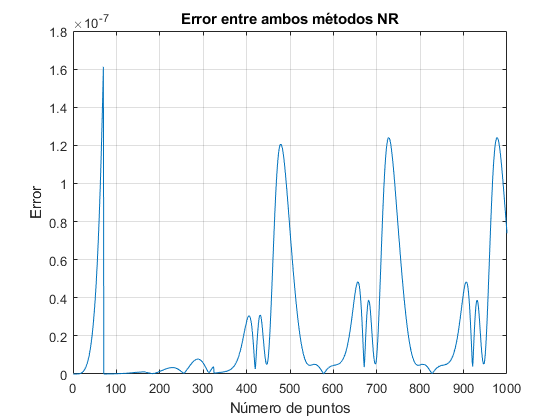

for i=1:length(ValoresSolucion_NR)
    Error_M(i)=norm(abs(ValoresSolucion_NR(i,:)-ValoresSolucion_NR_EX(i,:)));
end
figure()
plot(Error_M)
title("Error entre ambos métodos NR")
xlabel("Número de puntos")
ylabel("Error")
grid on

### Tiempo de ejecución

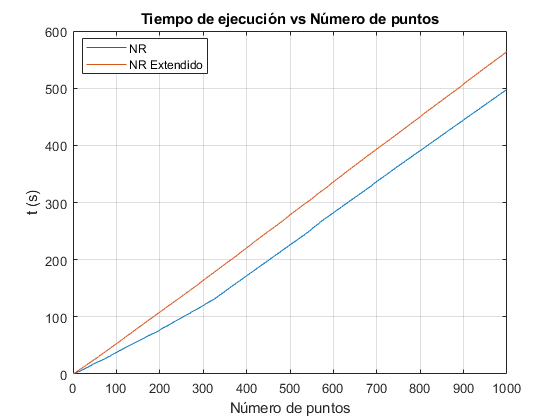

for i=1:length(tiepoEjeNR)
    tiempoTotalNr(i)=sum(tiepoEjeNR(1:i));
    
end

for i=1:length(tiempoEje_EX)
    tiempoTotalNrEX(i)=sum(tiempoEje_EX(1:i));
    
end
figure()
plot(tiempoTotalNr)
hold on
plot(tiempoTotalNrEX)
hold off
title("Tiempo de ejecución vs Número de puntos")
legend("NR","NR Extendido","Location","best")
grid on
ylabel("t (s)")
xlabel("Número de puntos")

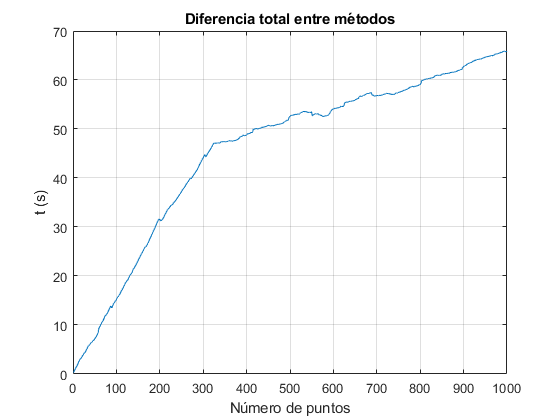


Diferencia=abs(tiempoTotalNr-tiempoTotalNrEX);
DiferenciaRelativa=Diferencia./tiempoTotalNr*100;
figure()
plot(Diferencia)
title("Diferencia total entre métodos")
xlabel("Número de puntos")
ylabel("t (s)")
grid on

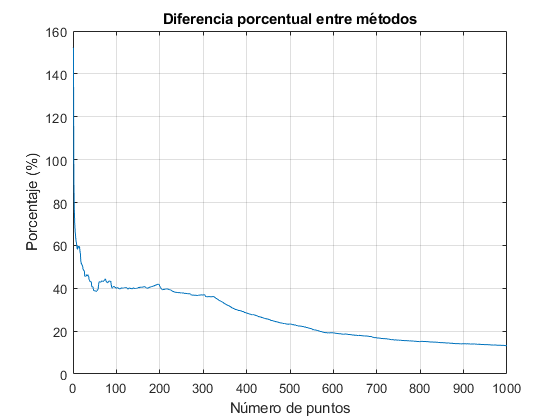

figure()
plot(DiferenciaRelativa)
title("Diferencia porcentual entre métodos")
ylabel("Porcentaje (%)")
xlabel("Número de puntos")
grid on

## Tabla de resultados

Tabla_Cinematica.R_1=ValoresSolucion_NR(:,1);
Tabla_Cinematica.theta_1=ValoresSolucion_NR(:,2);
Tabla_Cinematica.theta_3=ValoresSolucion_NR(:,3);
Tabla_Cinematica.V_1=ValoresSolucion_NR(:,4);
Tabla_Cinematica.omega_1=ValoresSolucion_NR(:,5);
Tabla_Cinematica.omega_3=ValoresSolucion_NR(:,6);
Tabla_Cinematica.a_1=ValoresSolucion_NR(:,7);
Tabla_Cinematica.alpha_1=ValoresSolucion_NR(:,8);
Tabla_Cinematica.alpha_3=ValoresSolucion_NR(:,9);
Tabla_Cinematica;
writetable(Tabla_Cinematica,'Resultados.txt','delimiter',' ', 'WriteVariableNames', true)

## Datos Inventor

t = xlsread("Resultados Inventor.xlsx");
TablaExcel=array2table(t);
TablaExcel.Properties.VariableNames=["Tiempo","Theta2","w2","A2","Theta3","W3","A3","R1","Vr1","Ar1"];


## Gráficas

### Perfil cinemático del motor

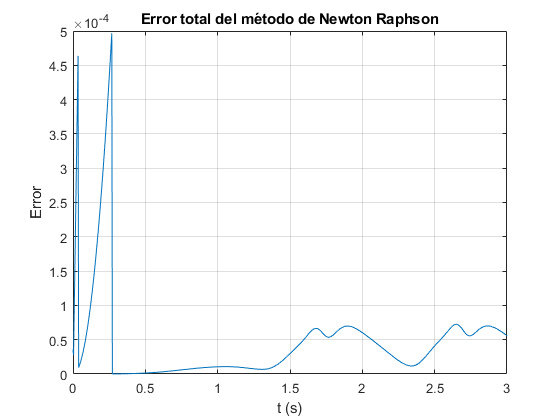


tiempo=Tabla_Cinematica.Tiempo;
ExTiempo=TablaExcel.Tiempo;
figure()
plot(tiempo,Error_NR)
title("Error total del método de Newton Raphson")
xlabel("t (s)")
ylabel("Error")
grid on
xlim([0 ExTiempo(end)])


Vmax=double(max(Tabla_Cinematica.Velocidad))*180/pi

Vmax = 370.8232

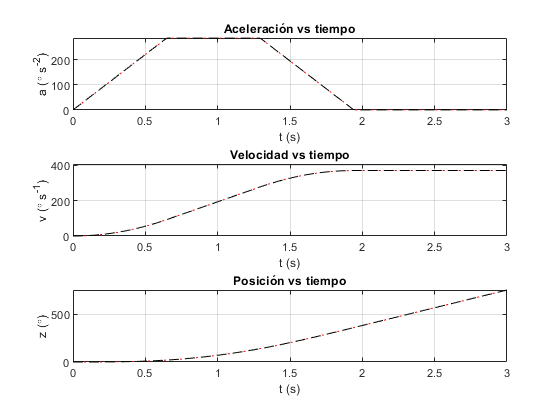

figure()
subplot(3,1,1)
plot(tiempo,Tabla_Cinematica.Aceleracion*180/pi,"r-.")
hold on
plot(ExTiempo,TablaExcel.A2*180/pi,"k--")
hold off
title('Aceleración vs tiempo')
grid on
xlabel('t (s)')
ylabel('a (\circ s^{-2})')
xlim([0 ExTiempo(end)])

subplot(3,1,2)
plot(tiempo,Tabla_Cinematica.Velocidad*180/pi,"r-.")
hold on
plot(ExTiempo,TablaExcel.w2*180/pi,"k--")
hold off
title('Velocidad vs tiempo')
grid on
xlabel('t (s)')
ylabel('v (\circ s^{-1})')
ylim([0 Vmax*1.1])
xlim([0 ExTiempo(end)])

subplot(3,1,3)
plot(tiempo,Tabla_Cinematica.Posicion*180/pi,"r-.")
hold on
plot(ExTiempo,TablaExcel.Theta2*180/pi,"k--")
hold off
title('Posición vs tiempo')
grid on
xlabel('t (s)')
ylabel('z (\circ)')
xlim([0 ExTiempo(end)])

### Gráficas de simulación y NR

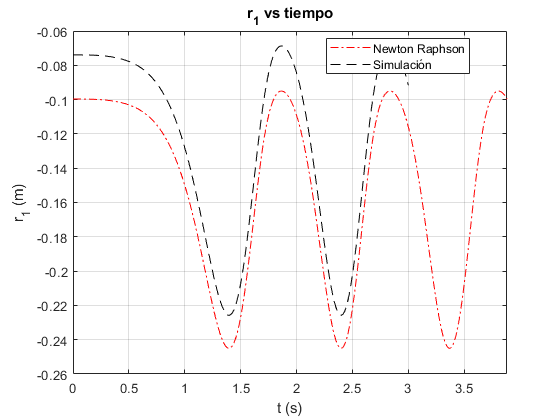

figure()
plot(tiempo,Tabla_Cinematica.R_1,"r-.")
hold on
plot(ExTiempo,TablaExcel.R1,"k--")
hold off
title("r_1 vs tiempo")
xlabel("t (s)")
ylabel("r_1 (m)")
grid on
xlim([0 tiempo(end)])
legend("Newton Raphson","Simulación","Location","best")

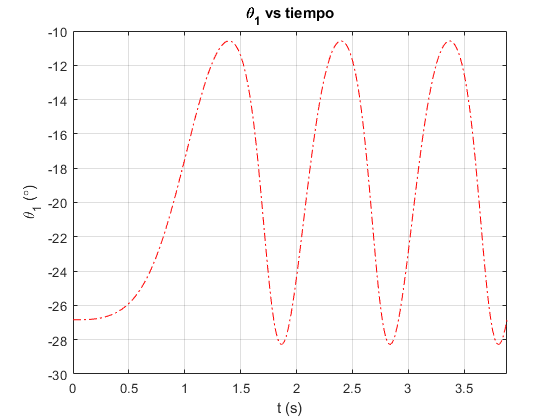


figure()
plot(tiempo,Tabla_Cinematica.theta_1*180/pi,"r-.")
title("\theta_1 vs tiempo")
xlabel("t (s)")
ylabel("\theta_1 (\circ)")
grid on
xlim([0 tiempo(end)])

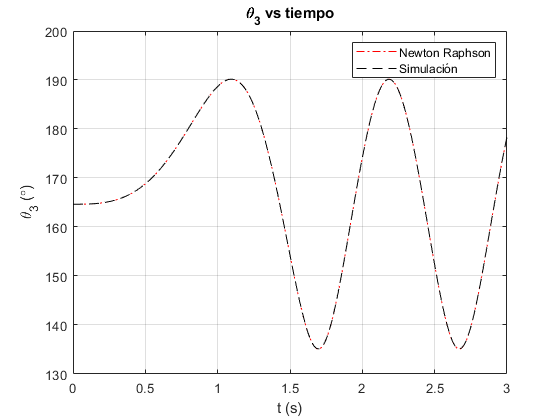


figure()
plot(tiempo,Tabla_Cinematica.theta_3*180/pi,"r-.")
hold on
plot(ExTiempo,TablaExcel.Theta3*180/pi,"k--")
hold off
title("\theta_3 vs tiempo")
xlabel("t (s)")
ylabel("\theta_3 (\circ)")
grid on
xlim([0 ExTiempo(end)])
legend("Newton Raphson","Simulación")

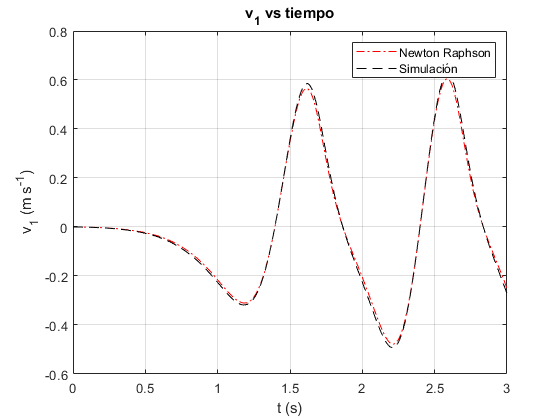



figure()
plot(tiempo,Tabla_Cinematica.V_1,"r-.")
hold on
plot(ExTiempo,TablaExcel.Vr1,"k--")
hold off
title("v_1 vs tiempo")
xlabel("t (s)")
ylabel("v_1 (m s^{-1})")
grid on
xlim([0 ExTiempo(end)])
legend("Newton Raphson","Simulación")

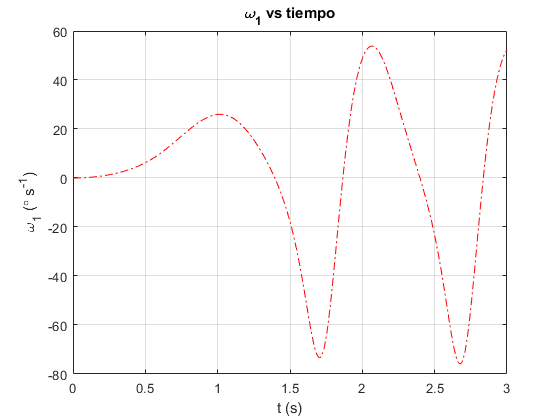


figure()
plot(tiempo,Tabla_Cinematica.omega_1*180/pi,"r-.")
title("\omega_1 vs tiempo")
xlabel("t (s)")
ylabel("\omega_1 (\circ s^{-1})")
grid on
xlim([0 ExTiempo(end)])

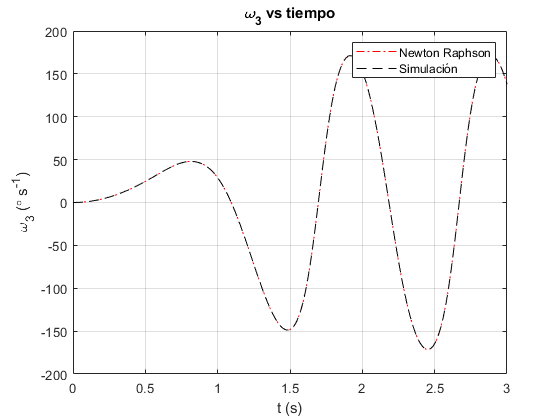


figure()
plot(tiempo,Tabla_Cinematica.omega_3*180/pi,"r-.")
hold on
plot(ExTiempo,TablaExcel.W3*180/pi,"k--")
hold off
title("\omega_3 vs tiempo")
xlabel("t (s)")
ylabel("\omega_3 (\circ s^{-1})")
grid on
xlim([0 ExTiempo(end)])
legend("Newton Raphson","Simulación")

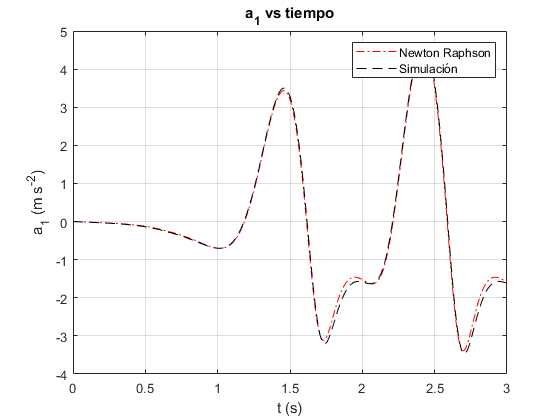


figure()
plot(tiempo,Tabla_Cinematica.a_1,"r-.")
hold on
plot(ExTiempo,TablaExcel.Ar1,"k--")
hold off
title("a_1 vs tiempo")
xlabel("t (s)")
ylabel("a_1 (m s^{-2})")
grid on
xlim([0 ExTiempo(end)])
legend("Newton Raphson","Simulación")

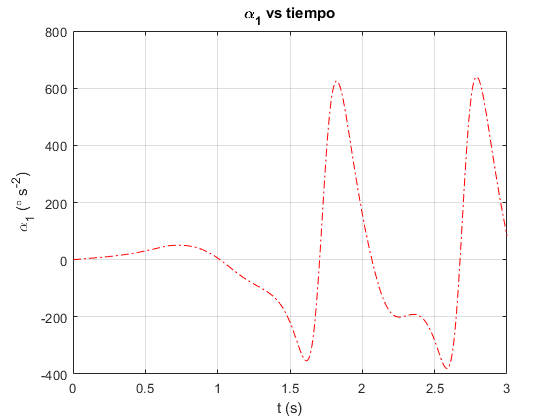


figure()
plot(tiempo,Tabla_Cinematica.alpha_1*180/pi,"r-.")
title("\alpha_1 vs tiempo")
xlabel("t (s)")
ylabel("\alpha_1 (\circ s^{-2})")
grid on
xlim([0 ExTiempo(end)])

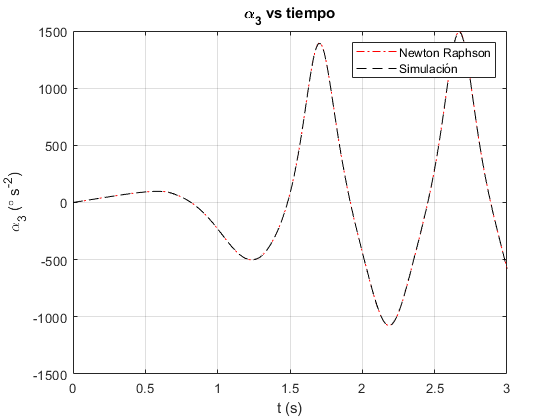


figure()
plot(tiempo,Tabla_Cinematica.alpha_3*180/pi,"r-.")
hold on
plot(ExTiempo,TablaExcel.A3*180/pi,"k--")
hold off
title("\alpha_3 vs tiempo")
xlabel("t (s)")
ylabel("\alpha_3 (\circ s^{-2})")
grid on
xlim([0 ExTiempo(end)])
legend("Newton Raphson","Simulación")

function [Sol,Error]= NR_Sistema(F,FJacInv,Pi,Ftheta_2,Fomega_2,Falpha_2)
syms omega_2 theta_2 alpha_2 
f=subs(F,[theta_2,omega_2,alpha_2],[Ftheta_2,Fomega_2,Falpha_2]);
JacInv=subs(FJacInv,[theta_2,omega_2,alpha_2],[Ftheta_2,Fomega_2,Falpha_2]);
p=Pi';
ValoresNR(1,:)=p';
iteraciones=50;
for i=1:iteraciones
    p=double(p-JacInv(p(1),p(2),p(3),p(4),p(5),p(6),p(7),p(8),p(9))*f(p(1),p(2),p(3),p(4),p(5),p(6),p(7),p(8),p(9)));
    ValoresNR(i+1,:)=double(p)';
    ErrorNR(i,:)=abs(ValoresNR(i,:)-ValoresNR(i+1,:));
    NormErrorNR(i)=norm(ErrorNR(i,:));
     if NormErrorNR(i)<0.0005
        break;
    end
end
    Error=NormErrorNR(end);
    Sol=p';
end


function [Sol,Error]= NR_Sistema_extenso(fP,JacInvP,fV,JacInvV,fA,JacInvA,Pi,Vtheta_2,Vomega_2,Valpha_2)
syms  r_1y r_1 r_2 r_3 theta_3 theta_2 theta_1 V_r omega_1 omega_2 omega_3 a_r alpha_1 alpha_2 alpha_3

fP=subs(fP,theta_2,Vtheta_2);
PiP=[Pi(1),Pi(2),Pi(3)]';
ValoresNR(1,:)=PiP';
iteraciones=15;
for i=1:iteraciones
    PiP=double(PiP-JacInvP(PiP(1),PiP(2),PiP(3))*fP(PiP(1),PiP(2),PiP(3)));
    ValoresNR(i+1,:)=double(PiP)';
    ErrorNR_P(i,:)=abs(ValoresNR(i,:)-ValoresNR(i+1,:));
    NormErrorNR_P(i)=norm(ErrorNR_P(i,:));
     if NormErrorNR_P(i)<0.0005
        break;
    end
end
SolPosNR=PiP;
ErrorP=NormErrorNR_P(end);

fV=subs(fV,[theta_2,r_1,theta_1,theta_3,omega_2],[Vtheta_2,SolPosNR(1),SolPosNR(2),SolPosNR(3),Vomega_2]);
JacInvV=subs(JacInvV,[theta_2,r_1,theta_1,theta_3,omega_2],[Vtheta_2,SolPosNR(1),SolPosNR(2),SolPosNR(3),Vomega_2]);
PiV=[Pi(4),Pi(5),Pi(6)]';
ValoresVNR(1,:)=PiV';
iteraciones=15;
for i=1:iteraciones

    PiV=double(PiV-JacInvV(PiV(1),PiV(2),PiV(3))*fV(PiV(1),PiV(2),PiV(3)));
    ValoresVNR(i+1,:)=double(PiV)';
    ErrorNR_V(i,:)=abs(ValoresVNR(i,:)-ValoresVNR(i+1,:));
    NormErrorNR_V(i)=norm(ErrorNR_V(i,:));
     if NormErrorNR_V(i)<0.0005
        break;
    end
end
SolVelNR=double(PiV);
ErrorV=NormErrorNR_V(end);

fA=subs(fA,[theta_2,r_1,theta_1,theta_3,omega_2,V_r,omega_1,omega_3,alpha_2],[Vtheta_2,SolPosNR(1),SolPosNR(2),SolPosNR(3),Vomega_2,SolVelNR(1),SolVelNR(2),SolVelNR(3),Valpha_2]);
JacInvA=subs(JacInvA,[theta_2,r_1,theta_1,theta_3,omega_2,V_r,omega_1,omega_3,alpha_2],[Vtheta_2,SolPosNR(1),SolPosNR(2),SolPosNR(3),Vomega_2,SolVelNR(1),SolVelNR(2),SolVelNR(3),Valpha_2]);
PiA=[Pi(7),Pi(8),Pi(9)]';
ValoresVNR(1,:)=PiA';
iteraciones=15;
for i=1:iteraciones
    PiA=double(PiA-JacInvA(PiA(1),PiA(2),PiA(3))*fA(PiA(1),PiA(2),PiA(3)));
    ValoresVNR(i+1,:)=double(PiA)';
    ErrorNR_A(i,:)=abs(ValoresVNR(i,:)-ValoresVNR(i+1,:));
    NormErrorNR_A(i)=norm(ErrorNR_A(i,:));
     if NormErrorNR_A(i)<0.0005
        break;
    end
end
SolAceNR=double(PiA);
ErrorA=NormErrorNR_A(end);
Sol=[SolPosNR',SolVelNR',SolAceNR'];
Error=norm([ErrorP,ErrorV,ErrorA]);
end
